load"C:\Users\anand\OneDrive\Desktop\Dissertation\prog\workspace  allll.mat"


net = trainedNetwork_1;
lgraph = layerGraph(net);
lgraph = removeLayers(lgraph,lgraph.Layers(end).Name);
dlnet = dlnetwork(lgraph);

Extract the class labels.

classes = categories(net.Layers(end).Classes)

classes = 5×1 cell array
    {'baboon'   }
    {'candle'   }
    {'cats'     }
    {'dogs'     }
    {'hourglass'}


Load an image to use to generate an adversarial example. The image is a picture of a golden retriever.

sherlock = "C:\Users\anand\OneDrive\Desktop\sherlock.jpg"

sherlock = "C:\Users\anand\OneDrive\Desktop\sherlock.jpg"

img = imread(sherlock);
T = "dogs";

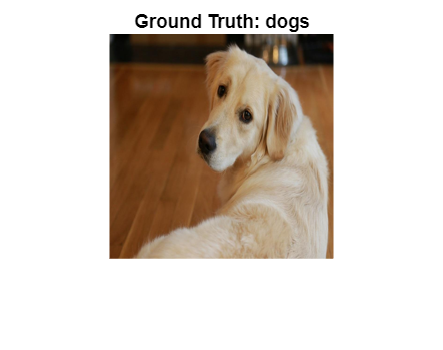

inputSize = dlnet.Layers(1).InputSize;
img = imresize(img,inputSize(1:2));

figure
imshow(img)
title("Ground Truth: " + T)

Prepare the image by converting it to a `dlarray`.

X = dlarray(single(img),"SSCB");

Prepare the label by one-hot encoding it.

T = onehotencode(T,1,'ClassNames',classes);
T = dlarray(single(T),"CB");

## Untargeted Fast Gradient Sign Method

Create an adversarial example using the untargeted FGSM [3]. This method calculates the gradient $\nabla_X L\left(X,T\right)$ of the loss function $L$, with respect to the image $X$ you want to find an adversarial example for, and the class label $T$. This gradient describes the direction to "push" the image in to increase the chance it is misclassified. You can then add or subtract a small error from each pixel to increase the likelihood the image is misclassified. 

The adversarial example is calculated as follows:

$X_{\textrm{adv}} =X+\epsilon \ldotp \textrm{sign}\left(\nabla_X L\left(X,T\right)\right)$.

Parameter $\epsilon$ controls the size of the push. A larger $\epsilon$ value increases the chance of generating a misclassified image, but makes the change in the image more visible. This method is untargeted, as the aim is to get the image misclassified, regardless of which class.

Calculate the gradient of the image with respect to the golden retriever class.

gradient = dlfeval(@untargetedGradients,dlnet,X,T);

Set `epsilon` to 1 and generate the adversarial example.

epsilon = 1;
XAdv = X + epsilon*sign(gradient);

Predict the class of the original image and the adversarial image.

YPred = predict(dlnet,X);
YPred = onehotdecode(squeeze(YPred),classes,1)

YPred = categorical
     dogs 


YPredAdv = predict(dlnet,XAdv);
YPredAdv = onehotdecode(squeeze(YPredAdv),classes,1)

YPredAdv = categorical
     dogs 


Display the original image, the perturbation added to the image, and the adversarial image. If the `epsilon` value is large enough, the adversarial image has a different class label from the original image.

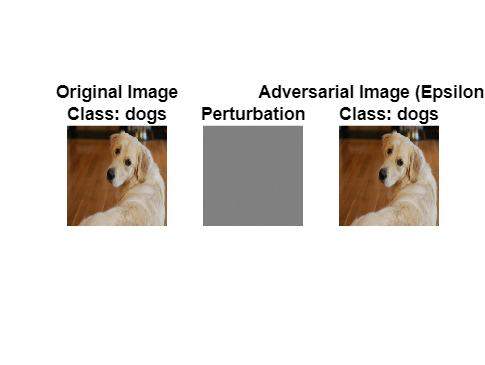

showAdversarialImage(X,YPred,XAdv,YPredAdv,epsilon);

The network correctly classifies the unaltered image as a golden retriever. However, because of perturbation, the network misclassifies the adversarial image as a labrador retriever. Once added to the image, the perturbation is imperceptible, demonstrating how adversarial examples can exploit robustness issues within a network.

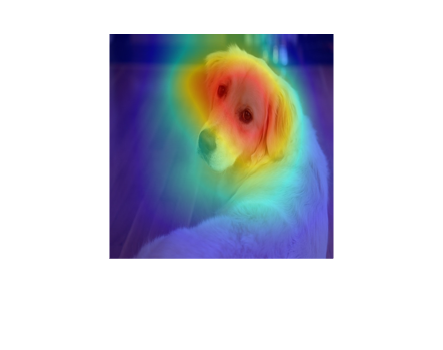

scoreMap = gradCAM(net,X,YPred);
gradimg = uint8(extractdata(X));
figure
imshow(gradimg)

hold on
imagesc(scoreMap,'AlphaData',0.5)
colormap jet

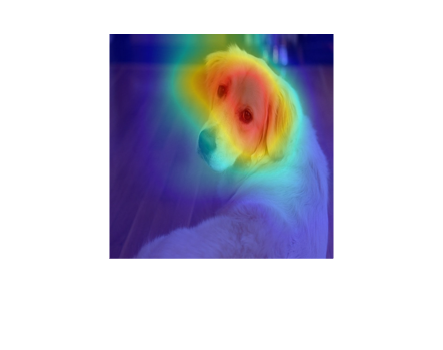



scoreMap1 = gradCAM(net,XAdv,YPredAdv);
gradimg1 = uint8(extractdata(XAdv));
figure
imshow(gradimg1)

hold on
imagesc(scoreMap1,'AlphaData',0.5)
colormap jet

segmentationMap = zeros(inputSize(1));

blockSize = 56;

segmentationSubset = ones(blockSize);
segmentationSubset = tril(segmentationSubset) + segmentationSubset;

% Set the diagonal elements to alternate values 1 and 2.
segmentationSubset(1:(blockSize+1):end) = repmat([1 2],1,blockSize/2)';

blocksPerSide = inputSize(1)/blockSize;
subset = 0;
for i=1:blocksPerSide
    for j=1:blocksPerSide
        xidx = (blockSize*(i-1))+1:(blockSize*i);
        yidx = (blockSize*(j-1))+1:(blockSize*j);
        segmentationMap(xidx,yidx) = segmentationSubset + 2*subset;
        subset = subset + 1;
    end
end



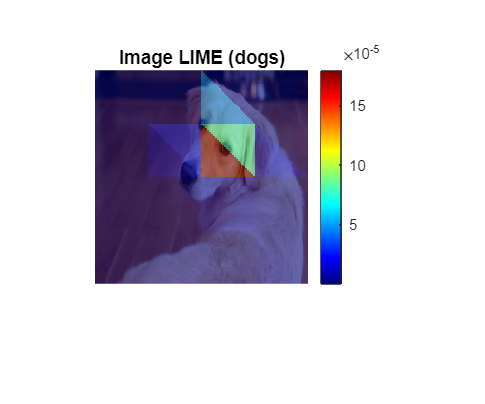

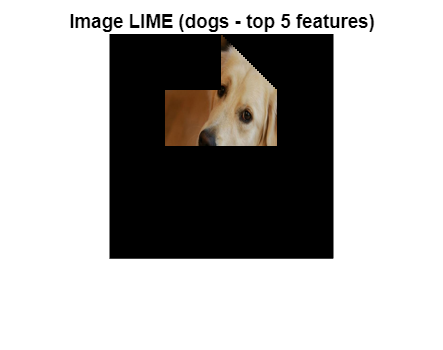

visualizeLIME(net, X, YPred,5,segmentationMap)

visualizeTopClasses(net, gradimg, classes)

ans = 5×2 cell array
    {'dogs'     }    {[    1.0000]}
    {'cats'     }    {[3.1830e-06]}
    {'hourglass'}    {[1.0996e-07]}
    {'candle'   }    {[4.8693e-08]}
    {'baboon'   }    {[4.9828e-09]}


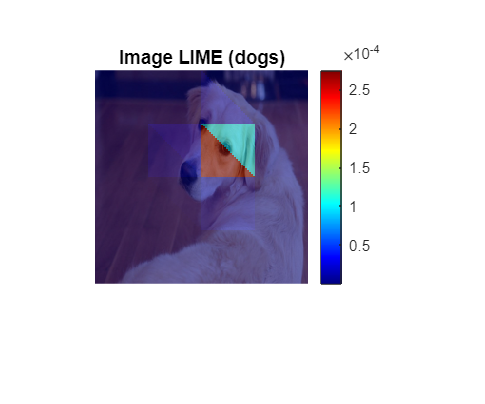

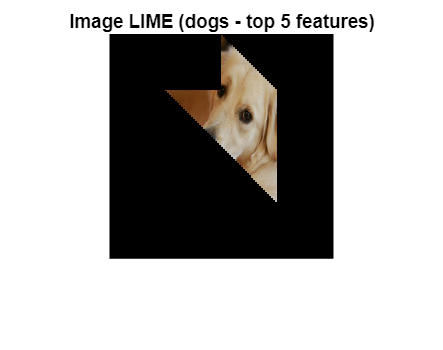

visualizeLIME(net, XAdv, YPredAdv,5 ,segmentationMap)

visualizeTopClasses(net, gradimg1, classes)

ans = 5×2 cell array
    {'dogs'     }    {[    0.9946]}
    {'cats'     }    {[    0.0054]}
    {'hourglass'}    {[1.2951e-05]}
    {'candle'   }    {[7.4207e-06]}
    {'baboon'   }    {[6.5183e-07]}


function combinedMatrix = visualizeTopClasses(net, img, classes)
    % Perform classification

    [~, scores] = classify(net, img);

    % Extract top 5 classes and scores
    [~, topIdx] = maxk(scores, 5);
    topScores = scores(topIdx);
    topClasses = classes(topIdx);

    % Display the image
    
    % Convert scores to cell and create the combined matrix
    tt = num2cell(topScores');
    combinedMatrix = [topClasses, tt];
end

**LIME FUNCTION **

function visualizeLIME(net, XAdvTarget, YPredAdvTarget ,no,segmentationMap)
    % Convert adversarial data to uint8
    advimg = uint8(extractdata(XAdvTarget));

    % Compute image LIME map
    map = imageLIME(net, advimg, YPredAdvTarget,'Segmentation',segmentationMap);

    % Display adversarial image with LIME overlay
    figure;
    imshow(advimg, 'InitialMagnification', 150);
    hold on;
    imagesc(map, 'AlphaData', 0.5);
    colormap jet;
    colorbar;
    title(sprintf("Image LIME (%s)", YPredAdvTarget));
    hold off;

    % Extract additional LIME information
    [map, featureMap, featureImportance] = imageLIME(net, advimg, YPredAdvTarget,'Segmentation',segmentationMap);

    % Extract top features
    numTopFeatures = no;
    [~, idx] = maxk(featureImportance, numTopFeatures);
    mask = ismember(featureMap, idx);
    maskedImg = uint8(mask) .* advimg;

    % Display adversarial image highlighting top features
    figure;
    imshow(maskedImg);
    title(sprintf("Image LIME (%s - top %i features)", YPredAdvTarget, numTopFeatures));
end


## Supporting Functions

### Untargeted Input Gradient Function

Calculate the gradient used to create an untargeted adversarial example. This gradient is the gradient of the cross-entropy loss.

function gradient = untargetedGradients(dlnet,X,target)

Y = predict(dlnet,X);
Y = stripdims(squeeze(Y));
loss = crossentropy(Y,target,'DataFormat','CB');
gradient = dlgradient(loss,X);

end

### Targeted Input Gradient Function

Calculate the gradient used to create a targeted adversarial example. This gradient is the gradient of the mean squared error.

function gradient = targetedGradients(dlnet,X,target)

Y = predict(dlnet,X);
Y = stripdims(squeeze(Y));
loss = mse(Y,target,'DataFormat','CB');
gradient = dlgradient(loss,X);

end

### Show Adversarial Image

Show an image, the corresponding adversarial image, and the difference between the two (perturbation).

function showAdversarialImage(image,label,imageAdv,labelAdv,epsilon)

figure
subplot(1,3,1)
imgTrue = uint8(extractdata(image));
imshow(imgTrue)
title("Original Image" + newline + "Class: " + string(label))

subplot(1,3,2)
perturbation = uint8(extractdata(imageAdv-image+127.5));
imshow(perturbation)
title("Perturbation")

subplot(1,3,3)
advImg = uint8(extractdata(imageAdv));
imshow(advImg)
title("Adversarial Image (Epsilon = " + string(epsilon) + ")" + newline + ...
    "Class: " + string(labelAdv))
end
